# Extracting multi-unit activity from ECog recording

First, we load data from 'ECoGData_AvailabletoStudents.mat'

data = load('ECoGData_AvailabletoStudents.mat').data;
fprintf('Sampling Freq: %.4f \n',data.SamplingFreq);

Sampling Freq: 24414.0625 


We get three singals, three timestampes, and sampling freuqnecy for the file. 

SamplingFreq = data.SamplingFreq;
Sig1 = data.Signal{1};
Sig2 = data.Signal{2};
Sig3 = data.Signal{3};
StimTime1 = data.StimTimes{1};
StimTime2 = data.StimTimes{2};
StimTime3 = data.StimTimes{3};

Find the period

perid = 1/freq

period = 1/SamplingFreq;
Sig1_t = 0+period:period:period*size(Sig1,1);
Sig2_t = 0+period:period:period*size(Sig2,1);
Sig3_t = 0+period:period:period*size(Sig3,1);

Raw signal looks like these:

plot(Sig1_t,Sig1)
title("Signal 1") % Constant

plot(Sig2_t,Sig2)
title("Signal 2") % 3Hz

plot(Sig3_t,Sig3)
title("Signal 3") % 10Hz

We use filter500to5k function() for filtering each signal between 500 to 5000Hz.

% Filter raw signal using highpass filtering
[SOS, G] = filter500to5k(SamplingFreq);
Sig1 = filtfilt(SOS,G,Sig1);

Sig2 = filtfilt(SOS,G,Sig2);

Sig3 = filtfilt(SOS,G,Sig3);

Draw filtered signal.

% Draw filtered signal
plot(Sig1_t,Sig1)
title("Signal 1") % Constant

plot(Sig2_t,Sig2)
title("Signal 2") % 3Hz

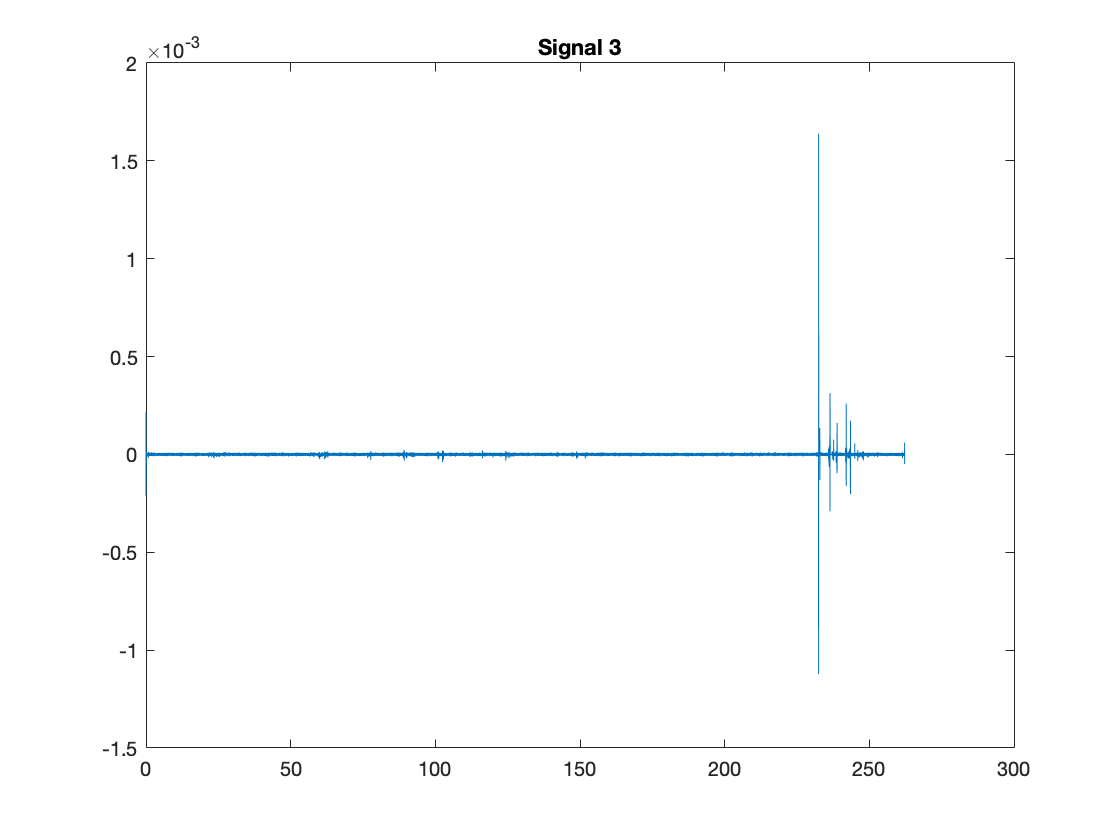

plot(Sig3_t,Sig3)
title("Signal 3") % 10Hz

Use the following thereshold to detect the time of multi-unit activity for each stimulation pattern. 

sigma = median(|filtered signal| / 0.6745)

Threshold = 3*sigma

Thres1 = 3 * median(abs([Sig1])/0.6745);
Thres2 = 3 * median(abs([Sig2])/0.6745);
Thres3 = 3 * median(abs([Sig3])/0.6745);

Find the thresholds using the findpeaks()

[pks1,locs1] = findpeaks(Sig1,'MinPeakHeight',Thres1);
[pks2,locs2] = findpeaks(Sig2,'MinPeakHeight',Thres2);
[pks3,locs3] = findpeaks(Sig3,'MinPeakHeight',Thres3);

locs is showing Xth of firing. We need to change it to the time of the firing.

locs1 = locs1*period;
locs2 = locs2*period;
locs3 = locs3*period;

% get binary pick
% returns  binary matrix size: #ofTrial * total tick slot(2sec/perid)
% 1: firing, 0: no firing
binaryPks1 = logical(getBinaryPks(StimTime1, locs1, period));
binaryPks2 = logical(getBinaryPks(StimTime2, locs2, period));
binaryPks3 = logical(getBinaryPks(StimTime3, locs3, period));

Plot the timing of each multinuit activity during each trail (from 0.5 seconds before stimulation after stimulation stops) for all 50 trials.

% Plot Signal 1
LineFormatVert.LineWidth = 0.7;
rectangle(Position=[fix(size(binaryPks1,2)*1/4),0, fix(size(binaryPks1,2)*1/2),50], FaceColor=[0.8 0.8 0.9]);
plotSpikeRaster(binaryPks1,'PlotType','vertline','LineFormat',LineFormatVert,'VertSpikePosition', -0.5);
xticks([0 fix(size(binaryPks1,2)*1/4) fix(size(binaryPks1,2)*3/4) size(binaryPks1,2)]);
xticklabels({'-0.5s' '0s' '1s' '+0.5s'});
title('Signal 1');

clf reset

% Plot Signal 2
rectangle(Position=[fix(size(binaryPks2,2)*1/4),0, fix(size(binaryPks2,2)*1/2),50], FaceColor=[0.8 0.8 0.9]);
plotSpikeRaster(binaryPks2,'PlotType','vertline','LineFormat',LineFormatVert,'VertSpikePosition', -0.5);
xticks([0 fix(size(binaryPks2,2)*1/4) fix(size(binaryPks2,2)*3/4) size(binaryPks2,2)]);
xticklabels({'-0.5s' '0s' '1s' '+0.5s'});
title('Signal 2');

clf reset

% Plot Signal 3
rectangle(Position=[fix(size(binaryPks3,2)*1/4),0, fix(size(binaryPks3,2)*1/2),50], FaceColor=[0.8 0.8 0.9]);
plotSpikeRaster(binaryPks3,'PlotType','vertline','LineFormat',LineFormatVert,'VertSpikePosition', -0.5);
xticks([0 fix(size(binaryPks3,2)*1/4) fix(size(binaryPks3,2)*3/4) size(binaryPks3,2)]);
xticklabels({'-0.5s' '0s' '1s' '+0.5s'});
title('Signal 3');

clf reset

% 20ms (20e-3)
BIN_SIZE_SEC = 20e-3;
nTrial = length(StimTime1); %50
nBin = fix(BIN_SIZE_SEC/period); %488

% Average pick per each period 
avePks1 = mean(binaryPks1);
avePks2 = mean(binaryPks2);
avePks3 = mean(binaryPks3);

% Init firingRates with zeros
firingRate1 = zeros(1,fix(2/period/nBin));
firingRate2 = zeros(1,fix(2/period/nBin));
firingRate3 = zeros(1,fix(2/period/nBin));

% Calcurate each firing rates (sum of picks /time)
for i = 0:fix(2/period/nBin)-1 % 0:99 
    firingRate1(1,i+1) = sum(avePks1(nBin*i+1 : nBin*i+nBin))/BIN_SIZE_SEC;
    firingRate2(1,i+1) = sum(avePks2(nBin*i+1 : nBin*i+nBin))/BIN_SIZE_SEC;
    firingRate3(1,i+1) = sum(avePks3(nBin*i+1 : nBin*i+nBin))/BIN_SIZE_SEC;
end

% Signal 1 / Firing Rates
hold on
plot(firingRate1)
xlim([0 fix(2/period/nBin)+1])
title('Signal1 Firing Rates')
xline([fix(size(firingRate1,2)*1/4), fix(size(firingRate1,2)*3/4)])
xticks([0 fix(size(firingRate1,2)*1/4) fix(size(firingRate1,2)*3/4) size(firingRate1,2)]);
xticklabels({'-0.5s' '0s' '1s' '+0.5s'});
ylabel('Firing Rates(Hz)')
xlabel('Time')
hold off

clf reset

% Signal 2 / Firing Rates
hold on
plot(firingRate2)
xlim([0 fix(2/period/nBin)+1])
title('Signal2 Firing Rates')
xline([fix(size(firingRate2,2)*1/4), fix(size(firingRate2,2)*3/4)])
xticks([0 fix(size(firingRate2,2)*1/4) fix(size(firingRate2,2)*3/4) size(firingRate2,2)]);
xticklabels({'-0.5s' '0s' '1s' '+0.5s'});
ylabel('Firing Rates(Hz)')
xlabel('Time')
hold off

clf reset

% Signal 3 / Firing Rates
hold on
plot(firingRate3)
xlim([0 fix(2/period/nBin)])
title('Signal3 Firing Rates')
xline([fix(size(firingRate3,2)*1/4), fix(size(firingRate3,2)*3/4)])
xticks([0 fix(size(firingRate3,2)*1/4) fix(size(firingRate3,2)*3/4) size(firingRate3,2)]);
xticklabels({'-0.5s' '0s' '1s' '+0.5s'});
ylabel('Firing Rates(Hz)')
xlabel('Time')
hold off

clf reset


function [binaryPks] = getBinaryPks(StimTime, locs, period)
% Changed to the Binary Spikes
% First, create empty cell 
nTrial = length(StimTime);
nSlot = fix(2/period); % 2sec(0.5+1+0.5)/ perid = # of total tick slots per trial
binaryPks = logical(zeros(nTrial,nSlot)); % 0 matrix - size: 50(#ofTrial)*48828

iloc_start = 1;
for istmT = 1:nTrial
    stmT = StimTime(istmT,1);
    beforeStimT = stmT-0.5;
    afterStimT = stmT+1+0.5;
    for iloc = iloc_start:length(locs)
        loc = locs(iloc,1);
        if loc > afterStimT
            iloc_start = iloc;
            break
        elseif loc>=beforeStimT && loc<=afterStimT
            % between 0.5 before - 0.5 after stim window --> Draw
            colIndex = fix(loc/period) - fix(beforeStimT/period);
            binaryPks(istmT,colIndex) = 1;
        end
    end
    %rawIndex = rawIndex-1;
end
end

function [SOS, G] = filter500to5k(Fs)
%FILTER500TO5K Returns a discrete-time filter matrix SOS and scale values G.
% MATLAB Code
% Generated by MATLAB(R) 8.1 and the Signal Processing Toolbox 6.19.
% Generated on: 01-Nov-2013 15:23:14
% Butterworth Bandpass filter designed using FDESIGN.BANDPASS.
% All frequency values are in Hz.
N   = 2;     % Order
Fc1 = 500;   % First Cutoff Frequency
Fc2 =5000;  % Second Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
%disp(h)
Hd = design(h, 'butter');
SOS = Hd.sosMatrix;
G = Hd.ScaleValues;
% [EOF]
end

function [xPoints, yPoints] = plotSpikeRaster(spikes,varargin)
% PLOTSPIKERASTER Create raster plot from binary spike data or spike times
%   Efficiently creates raster plots with formatting support. Faster than
%   common implementations. Multiple plot types and parameters available!
%   Look at Parameters section below.
% 
%   Inputs:
%       M x N logical array (binary spike data):
%           where M is the number of trials and N is the number of time
%           bins with maximum of 1 spike per bin. Assumes time starts at 0.
%       M x 1 cell of spike times:
%           M is the number of trials and each cell contains a 1 x N vector
%           of spike times. Units should be in seconds.
%
%   Output:
%       xPoints - vector of x points used for the plot.
%       yPoints - vector of y points used for the plot.
%
%   Parameters:
%       PlotType - default 'horzline'. Several types of plots available:
%           1. 'horzline' -     plots spikes as gray horizontal lines. 
%           2. 'vertline' -     plots spikes as vertical lines, centered
%               vertically on the trial number. 
%           3. 'scatter' -      plots spikes as gray dots.
%
%           ONLY FOR BINARY SPIKE DATA:
%           4. 'imagesc' -      plots using imagesc. Flips colormap so
%               black indicates a spike. Not affected by SpikeDuration,
%               RelSpikeStartTime, and similar timing parameters.
%           5. 'horzline2' -    more efficient plotting than horzline if
%               you have many timebins, few trials, and high spike density.
%               Note: SpikeDuration parameter DOES NOT WORK IF LESS THAN 
%               TIME PER BIN.
%           6. 'vertline2' -    more efficient plotting than vertline if
%               you have few timebins, many trials, and high spike density.
%           Note: Horzline and vertline should be fine for most tasks.
% 
%       FigHandle - default gcf (get current figure).
%           Specify a specific figure or subplot to plot in. If no figure
%           is specified, plotting will occur on the current figure. If no
%           figure is available, a new figure will be created.
% 
%       LineFormat - default line is gray. Used for 'horzline' and
%           'vertline' plots only. Usage example:
%               LineFormat = struct()
%               LineFormat.Color = [0.3 0.3 0.3];
%               LineFormat.LineWidth = 0.35;
%               LineFormat.LineStyle = ':';
%               plotSpikeRaster(spikes,'LineFormat',LineFormat)
% 
%       MarkerFormat - default marker is a gray dot with size 1. Used for
%           scatter type plots only. Usage is the same as LineFormat.
% 
%       AutoLabel - default 0.
%           Automatically labels x-axis as 'Time (ms)' or 'Time (s)' and
%           y-axis as 'Trial'.
% 
%       XLimForCell - default [NaN NaN].
%           Sets x-axis window limits if using cell spike time data. If
%           unchanged, the default limits will be 0.05% of the range. For
%           better performance, this parameter should be set.
%
%       TimePerBin - default 0.001 (1 millisecond).
%           Sets the duration of each timebin for binary spike train data.
% 
%       SpikeDuration - default 0.001 (1 millisecond).
%           Sets the horizontal spike length for cell spike time data.
%
%       RelSpikeStartTime - default 0 seconds.
%           Determines the starting point of the spike relative to the time
%           indicated by spike times or time bins. For example, a relative
%           spike start time of -0.0005 would center 1ms spikes for a
%           horzline plot of binary spike data.
%
%       rasterWindowOffset - default NaN
%           Exactly the same as relSpikeStartTime, but unlike
%           relSpikeStartTime, the name implies that it can be used to make
%           x-axis start at a certain time. If set, takes precedence over
%           relSpikeStartTime.
%       
%       VertSpikePosition - default 0 (centered on trial).
%           Determines where the spike position is relative to the trial. A
%           value of 0 is centered on the trial number - so a spike on
%           trial 3 would have its y-center on 3. Example: A common type of
%           spike raster plots vertical spikes from previous trial to
%           current trial. Set VertSpikePosition to -0.5 to center the
%           spike between trials.
%
%       VertSpikeHeight - default 1 (spans 1 trial).
%           Determines height of spike for 'vertline' plots. Decrease to
%           separate trials with a gap.
%
%   Examples:
%       plotSpikeRaster(spikeTimes);
%               Plots raster plot with horizontal lines.
%
%       plotSpikeRaster(spikeTimes,'PlotType','vertline');
%               Plots raster plot with vertical lines.
%
%       plotSpikeRaster(spikeTimes,'FigHandle',h,'AutoLabel',1,...
%           'XLimForCell',[0 10],'HorzSpikeLength',0.002,); 
%               Plots raster plot on figure with handle h using horizontal
%               lines of length 0.002, with a window from 0 to 10 seconds,
%               and automatic labeling.
%
%       plotSpikeRaster(spikeTimes,'PlotType','scatter',...
%           'MarkerFormat',MarkerFormat);
%               Plots raster plot using dots with a format specified by
%               MarkerFormat.
%% AUTHOR    : Jeffrey Chiou
%% $DATE     : 07-Feb-2014 12:15:47 $
%% $Revision : 1.2 $
%% DEVELOPED : 8.1.0.604 (R2013a)
%% FILENAME  : plotSpikeRaster.m
%% Set Defaults and Load optional arguments
LineFormat.Color = [0.2 0.2 0.2];
MarkerFormat.MarkerSize = 1;
MarkerFormat.Color = [0.2 0.2 0.2];
MarkerFormat.LineStyle = 'none';
p = inputParser;
p.addRequired('spikes',@(x) islogical(x) || iscell(x));
p.addParamValue('FigHandle',gcf,@isinteger);
p.addParamValue('PlotType','horzLine',@ischar);
p.addParamValue('LineFormat',LineFormat,@isstruct)
p.addParamValue('MarkerFormat',MarkerFormat,@isstruct);
p.addParamValue('AutoLabel',1, @islogical);
p.addParamValue('XLimForCell',[NaN NaN],@(x) isnumeric(x) && isvector(x));
p.addParamValue('TimePerBin',0.001,@(x) isnumeric(x) && isscalar(x));
p.addParamValue('SpikeDuration',0.001,@(x) isnumeric(x) && isscalar(x));
p.addParamValue('RelSpikeStartTime',0,@(x) isnumeric(x) && isscalar(x));
p.addParamValue('RasterWindowOffset',NaN,@(x) isnumeric(x) && isscalar(x));
p.addParamValue('VertSpikePosition',0,@(x) isnumeric(x) && isscalar(x));
p.addParamValue('VertSpikeHeight',1,@(x) isnumeric(x) && isscalar(x));
p.parse(spikes,varargin{:});
spikes = p.Results.spikes;
figH = p.Results.FigHandle;
plotType = lower(p.Results.PlotType);
lineFormat = struct2opt(p.Results.LineFormat);
markerFormat = struct2opt(p.Results.MarkerFormat);
autoLabel = p.Results.AutoLabel;
xLimForCell = p.Results.XLimForCell;
timePerBin = p.Results.TimePerBin;
spikeDuration = p.Results.SpikeDuration;
relSpikeStartTime = p.Results.RelSpikeStartTime;
rasterWindowOffset = p.Results.RasterWindowOffset;
vertSpikePosition = p.Results.VertSpikePosition;
vertSpikeHeight = p.Results.VertSpikeHeight;
if ~isnan(rasterWindowOffset) && relSpikeStartTime==0
    relSpikeStartTime = rasterWindowOffset;
elseif ~isnan(rasterWindowOffset) && relSpikeStartTime~=0
    disp(['Warning: RasterWindoWOffset and RelSpikeStartTime perform the same function. '...
        'The value set in RasterWindowOffset will be used over RelSpikesStartTime']);
    relSpikeStartTime = rasterWindowOffset;
end
%% Initialize figure and begin plotting logic
figure(figH);
hold on;
if islogical(spikes)
    %% Binary spike train matrix case. Initialize variables and set axes.
    nTrials = size(spikes,1);  
    nTimes = size(spikes,2);
    % Convert Parameters to correct units using TimePerBin. Default is 1 ms
    % per bin (0.001s)
    spikeDuration = spikeDuration/timePerBin;
    relSpikeStartTime = relSpikeStartTime/timePerBin;
    
    % Note: xlim and ylim are much, much faster than axis or set(gca,...).
    xlim([0+relSpikeStartTime nTimes+1+relSpikeStartTime]);
    ylim([0 nTrials+1]);        
    
    switch plotType
        case 'horzline'
            %% Horizontal Lines
            % Find the trial (yPoints) and timebin (xPoints) of each spike
            [trials,timebins] = find(spikes);
            trials = trials';
            timebins = timebins';
            xPoints = [ timebins + relSpikeStartTime;
                        timebins + relSpikeStartTime + spikeDuration;
                        NaN(size(timebins)) ];
            yPoints = [ trials + vertSpikePosition;
                        trials + vertSpikePosition;
                        NaN(size(trials)) ];
                    
            xPoints = xPoints(:);
            yPoints = yPoints(:);
            plot(xPoints,yPoints,'k',lineFormat{:});
        case 'vertline'
            %% Vertical Lines
            % Find the trial (yPoints) and timebin (xPoints) of each spike
            [trials,timebins] = find(spikes);
            trials = trials';
            timebins = timebins';
            halfSpikeHeight = vertSpikeHeight/2;
            
            xPoints = [ timebins + relSpikeStartTime;
                        timebins + relSpikeStartTime;
                        NaN(size(timebins)) ];
            yPoints = [ trials - halfSpikeHeight + vertSpikePosition;
                        trials + halfSpikeHeight + vertSpikePosition;
                        NaN(size(trials)) ];
            xPoints = xPoints(:);
            yPoints = yPoints(:);
            plot(xPoints,yPoints,'k',lineFormat{:});
        case 'horzline2'
            %% Horizontal lines, for many timebins
            % Plots a horizontal line the width of a time bin for each
            % spike. Efficient for fewer trials and many timebins. 
            xPoints = [];
            yPoints = [];
            
            for trials = 1:nTrials
                % If there are spikes, plot a line. Otherwise, do nothing.
                if sum(spikes(trials,:)) > 0
                    
                    % Find the difference in spike times. Padding at the
                    % front and back with a zero accounts for spikes in
                    % the first and last indices, and keeps startY and endY
                    % the same size
                    spikeDiff = diff([0 spikes(trials,:) 0]);
                    % Ex. [0 1 1] -> [0 0 1 1 0]. diff(...) -> [0 1 0 -1]
                    
                    % Find line segments to plot (line segments longer than
                    % one trial are for spikes on consecutive trials)
                    startX = find(spikeDiff > 0);
                    % Ex. cont. from above: find(...) -> 2
                    endX = find(spikeDiff < 0);
                    % Ex. cont. from above: find(...) -> 4. Thus a line
                    % segment will be defined from 2 to 4 (x-axis)
                    
                    % Combine x points and adjust x points according to
                    % parameters. Add Add NaNs to break up line segments.
                    trialXPoints = [startX + relSpikeStartTime;...
                        endX + relSpikeStartTime + (spikeDuration - 1);...
                        NaN(size(startX)) ];
                    % Explanation for 'spikeDuration - 1': spikeDuration
                    % has been converted already using timePerBin, so the
                    % offset at the end is simply duration - one timeBin,
                    % since 1 timebin's worth of spikes has passed. Only
                    % affects last spike if less than time per bin.
                    % Convert x points array to vector
                    trialXPoints = trialXPoints(:)';
                    
                    % Add y points centered on the trial by default
                    % (adjustable with vertSpikePosition parameter)
                    trialYPoints = trials*ones(size(trialXPoints)) + vertSpikePosition;
                    
                    % Store this trial's x and y points. Unfortunately,
                    % preallocating and trimming may actually be slower,
                    % depending on data.
                    xPoints = [xPoints trialXPoints];
                    yPoints = [yPoints trialYPoints];
                    
                end
            end
            
            plot(xPoints, yPoints,'k', lineFormat{:});
            
        case 'vertline2'
            %% Vertical lines, for many trials
            % Plot one long line for each timebin. Reduces the number of
            % objects to plot. Efficient for many trials and fewer timebins            
            xPoints = [];
            yPoints = [];
            
            for time = 1:nTimes
                if sum(spikes(:,time)) > 0
                    
                    % Find the difference in spike times. Same principle as
                    % horzline2. See comments above for explanation.
                    spikeDiff = diff([0 spikes(:,time)' 0]);
                    
                    % Find line segments to plot (line segments longer than
                    % one trial are for spikes on consecutive trials)
                    startY = find(spikeDiff > 0);
                    endY = find(spikeDiff < 0);
                    
                    % Add NaNs to break up line segments
                    timeBinYPoints = [startY + vertSpikePosition;...
                        endY + vertSpikePosition; NaN(size(startY))];
                    % Convert to vector
                    timeBinYPoints = timeBinYPoints(:)';
                    timeBinXPoints = time*ones(size(timeBinYPoints));
                    
                    % Store this timebin's x and y points.
                    xPoints = [xPoints timeBinXPoints];
                    % Subtract 0.5 from each y point so spikes are centered
                    % by default (adjustable with vertSpikePosition)
                    yPoints = [yPoints timeBinYPoints-0.5];
                end
            end
            
            plot(xPoints, yPoints, 'k', lineFormat{:});
            
        case 'scatter'
            %% Dots or other markers (scatterplot style)
            % Find the trial (yPoints) and timebin (xPoints) of each
            % spike
            [yPoints,xPoints] = find(spikes==1);
            xPoints = xPoints + relSpikeStartTime;
            plot(xPoints,yPoints,'.k',markerFormat{:});
            
        case 'imagesc'
            %% Imagesc
            imagesc(spikes);
            % Flip the colormap since the default is white for 1, black for
            % 0.
            colormap(flipud(colormap('gray')));
            
        otherwise
            error('Invalid plot type. Must be horzline, vertline, horzline2, vertline2, scatter, or imagesc');
    end % switch
    set(gca,'YDir','reverse');
    
    %% Label
    if autoLabel
        xlabel('Time');
        ylabel('# of Trial');
    end
else % Equivalent to elseif iscell(spikes).
    %% Cell case
    
    % Validation: First check to see if cell array is a vector, and each
    % trial within is a vector.
    if ~isvector(spikes)
        error('Spike cell array must be an M x 1 vector.')
    end
    trialIsVector = cellfun(@isvector,spikes);
    if sum(trialIsVector) < length(spikes)
        error('Cells must contain 1 x N vectors of spike times.');
    end
    
    % Now make sure cell array is M x 1 and not 1 x M.
    if size(spikes,2) > 1 && size(spikes,1) == 1
        spikes = spikes';
    end
    
    % Make sure each trial is 1 x N and not N x 1
    nRowsInTrial = cellfun(@(x) size(x,1),spikes);
    % If there is more than 1 row in any trial, add a warning, and
    % transpose those trials. Allows for empty trials/cells (nRows > 1
    % instead of > 0).
    if sum(nRowsInTrial > 1) > 0 
        trialsToReformat = find(nRowsInTrial > 1);
        disp('Warning - some cells (trials) have more than 1 row. Those trials will be transposed.');
        for t = trialsToReformat
            spikes{trialsToReformat} = spikes{trialsToReformat}';
        end
    end
    
    nTrials = length(spikes);
    
    % Find x-axis limits that aren't manually set (default [NaN NaN]), and
    % automatically set them. This is because we don't assume spikes start
    % at 0 - we can have negative spike times.
    limitsToSet = isnan(xLimForCell);
    if sum(limitsToSet) > 0
        % First find range of spike times
        minTimes = cellfun(@min,spikes,'UniformOutput',false);
        minTime = min( [ minTimes{:} ] );
        maxTimes = cellfun(@max,spikes,'UniformOutput',false);
        maxTime = max( [ maxTimes{:} ] );
        timeRange = maxTime - minTime;
        
        % Find 0.05% of the range.
        xStartOffset = relSpikeStartTime - 0.0005*timeRange;
        xEndOffset = relSpikeStartTime + 0.0005*timeRange + spikeDuration;
        newLim = [ minTime+xStartOffset, maxTime+xEndOffset ];
        xLimForCell(limitsToSet) = newLim(limitsToSet);
        % End result, if both limits are automatically set, is that the x
        % axis is expanded 0.1%, so you can see initial and final spikes.
    end
    xlim(xLimForCell);
    ylim([0 nTrials+1]);
    
    if strcmpi(plotType,'vertline') || strcmpi(plotType,'horzline')
        %% Vertical or horizontal line logic
        nTotalSpikes = sum(cellfun(@length,spikes));
        
        % Preallocation is possible since we know how many points to
        % plot, unlike discrete case. 3 points per spike - the top pt,
        % bottom pt, and NaN.
        xPoints = NaN(nTotalSpikes*3,1);
        yPoints = xPoints;
        currentInd = 1;
        
        if strcmpi(plotType,'vertline')
            %% Vertical Lines
            halfSpikeHeight = vertSpikeHeight/2;
            for trials = 1:nTrials
                nSpikes = length(spikes{trials});
                nanSeparator = NaN(1,nSpikes);
                
                trialXPoints = [ spikes{trials} + relSpikeStartTime;...
                    spikes{trials} + relSpikeStartTime; nanSeparator ];
                trialXPoints = trialXPoints(:);
                
                trialYPoints = [ (trials-halfSpikeHeight)*ones(1,nSpikes);...
                    (trials+halfSpikeHeight)*ones(1,nSpikes); nanSeparator ];
                trialYPoints = trialYPoints(:);
                
                % Save points and update current index
                xPoints(currentInd:currentInd+nSpikes*3-1) = trialXPoints;
                yPoints(currentInd:currentInd+nSpikes*3-1) = trialYPoints;
                currentInd = currentInd + nSpikes*3;
            end
            
        else % (if plotType is 'horzline')
            %% Horizontal Lines
            for trials = 1:nTrials
                nSpikes = length(spikes{trials});                
                nanSeparator = NaN(1,nSpikes);
                
                trialXPoints = [ spikes{trials} + relSpikeStartTime;...
                    spikes{trials} + relSpikeStartTime + spikeDuration;...
                    nanSeparator ];
                trialXPoints = trialXPoints(:);
                
                trialYPoints = [ trials*ones(1,nSpikes);...
                    trials*ones(1,nSpikes); nanSeparator ];
                trialYPoints = trialYPoints(:);
                
                % Save points and update current index
                xPoints(currentInd:currentInd+nSpikes*3-1) = trialXPoints;
                yPoints(currentInd:currentInd+nSpikes*3-1) = trialYPoints;
                currentInd = currentInd + nSpikes*3;
            end
            
        end
        
        % Plot everything at once! We will reverse y-axis direction later.
        plot(xPoints, yPoints, 'k', lineFormat{:});
        
    elseif strcmpi(plotType,'scatter')
        %% Dots or other markers (scatterplot style)
        % Combine all spike times into one vector
        xPoints = [ spikes{:} ];
        
        % Getting the trials is trickier. 3 steps:
        % 1. First convert all the spike times into ones.
        trials = cellfun( @(x) {ones(size(x))}, spikes );
        % 2. Then multiply by trial number.
        for trialNum = 1:length(spikes)
            trials{trialNum} = trialNum*trials{trialNum};
        end
        % 3. Finally convert into a vector
        yPoints = [ trials{:} ];
        
        % Now we can plot! We will reverse y-axis direction later.
        plot(xPoints,yPoints,'.k',markerFormat{:});
        
    elseif strcmpi(plotType,'imagesc') || strcmpi(plotType,'vertline2') || strcmpi(plotType,'horzline2')
        error('Can''t use imagesc/horzline2/vertline2 with cell array. Use with logical array of binary spike train data.');
    else
        error('Invalid plot type. With cell array of spike times, plot type must be horzline, vertline, or scatter.');
    end % plot type switching
    
    %% Reverse y-axis direction and label
    set(gca,'YDir','reverse');
    if autoLabel
        xlabel('Time (s)');
        ylabel('Trial');
    end
    
end % logical vs cell switching
%% Figure formatting
% Draw the tick marks on the outside
set(gca,'TickDir','out') 
% Use special formatting if there is only a single trial.
% Source - http://labrigger.com/blog/2011/12/05/raster-plots-and-matlab/
if size(spikes,1) == 1
    set(gca,'YTick', [])                        % don't draw y-axis ticks
    set(gca,'PlotBoxAspectRatio',[1 0.05 1])    % short and wide
    set(gca,'YColor',get(gcf,'Color'))          % hide the y axis
    ylim([0.5 1.5])
end
hold off;
end % main function
function paramCell = struct2opt(paramStruct)
% Converts structure to parameter-value pairs
%   Example usage:
%       formatting = struct()
%       formatting.color = 'black';
%       formatting.fontweight = 'bold';
%       formatting.fontsize = 24;
%       formatting = struct2opt(formatting);
%       xlabel('Distance', formatting{:});
% Adapted from:
% http://stackoverflow.com/questions/15013026/how-can-i-unpack-a-matlab-structure-into-function-arguments
% by user 'yuk'
fname = fieldnames(paramStruct);
fval = struct2cell(paramStruct);
paramCell = [fname, fval]';
paramCell = paramCell(:);
end % struct2opt